# A classification example with simple stabSel calls: predicting low scorers on the Montreal Cognitive Assesment test for dementia using discourse measures 

Predicting song years is fun, but as you can see our predictions were rather poor. Let's look at a dataset that will be easier for us to model. In this example we've had 73 participants come in to the lab to perform the Montreal Cognitive Assesment (MoCA) test for dementia. Since lower scoring participants might be "at risk" for dementia, we would like to be able to predict them. Here, we're going to try doing this using participant performance on an arugably more ecologically valid and easier to perform/administer discourse task. In this discourse task, we extract lots of different language measures based on participants' spontaneous speech (i.e., their descriptions of various scenes). We are interested in seeing whether stability selection might improve our predictions, but we'll also try a few different algorithms for building our final predictions just to see if we can get better performance. 

Note, this data replicates analyses we reported in  Wilson et al (under review). To access the data that we will need follow this link: [https://osf.io/nwmqk/?view_only=b89f685641ec41b1aa607d181e235f27](https://osf.io/nwmqk/?view_only=b89f685641ec41b1aa607d181e235f27)

JFYI the first 4 models we will build show no improvement as a function of adding stabSel but the other models will see major gains. Feel free to skip around to the kNN and SVM models if you want to see examples where stabSel makes a difference. 

## Setting everything up

First, let's load in all of the data we'll need. For this, you want the inData.xlsx file. Make sure to specify your filepath

baseDir = '/home/rorden/pcr/'; % make this variable the path where you have placed inData.xslx
cd(baseDir)
inData = readtable([baseDir 'inData.xlsx'])

inData = 73×22 table
    x_duration_    x_MluUtts_    x_MluMorph_    x_Ttr_    x_WordsMin_    x_VerbsUtt_    x_WordErrors_    x_UttErrors_    x_PropDensity_    x_Retracings_    x_Rep_    x_FalseStarts_    x_Pauses_    x_totalMazes_    x_nouns_    x_pronouns_    x_pronounIndex_    x_perNouns_    x_perVerbs_    x_storyElementsRecalled_    x_percentStoryRetell_    moca_
    ___________    __________    ___________    ______    ___________    ___________    _____________    ____________   

As you can see from the table above, we have 22 variables in our spreadsheet. The very last variable is moca scores, which we'll try to predict. But first, we will convert these continuous scores into classes, separating everyone scoring above 26 from everyone scoring below 26 (i.e., low and high moca scorers). As you can see from the scatter plot below, we don't have too many participants with very low moca scores. Consequently, if we look at moca prediction as a regression problem, we're going to have some trouble properly learning what distinguishes participants with moca scores in the 18-22 range.

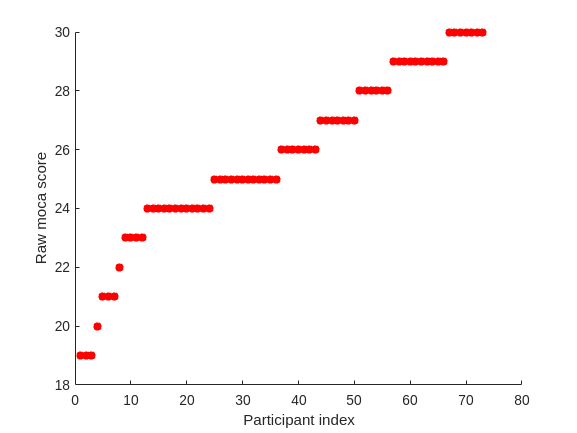

figure; scatter([1:size(inData.moca_)],inData.moca_,'Filled','MarkerFaceColor',[1 0 0]); xlabel('Participant index'); ylabel('Raw moca score')

id1 = find(inData.moca_ <= 25)

id1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


id2 = find(inData.moca_ > 25)

id2 =     37
    38
    39
    40
    41
    42
    43
    44
    45
    46


y(id1) = 1;
y(id2) = 2;

As you can see, doing this leaves us with classes that are similar in size so we don't have to worry about class imbalance.

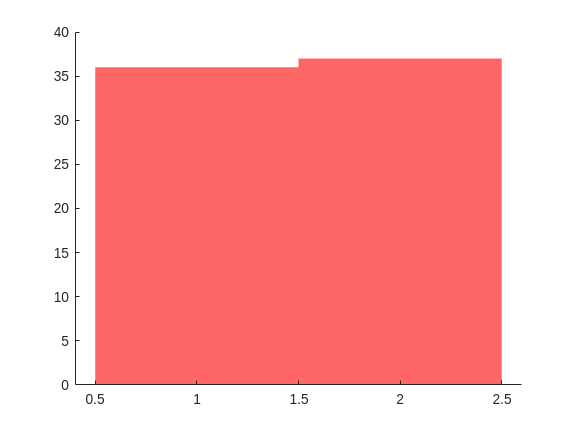

figure; histogram(y,'DisplayName','Classes','FaceColor',[1 0 0],'EdgeAlpha',0); box off

Now we need to setup our predictors. We'll use all of the language variables from the discourse task that we have access to, except we will exclude the number of story elements recalled. That's because this variable is redundant since we'll already have access to % story recall. Keeping the percentage measure for story recall is consistent with other measures, which are expressed as proportions instead of raw counts.

preds = table2array(inData(:,[1:19 21]));

We're getting close to being able to start making predictions! Only thing we need to address before we can get going is cross-validation. Let's do that now. We'll use leave one out cross-validation in the outer folds to measure our models' performance and 12-fold cross-validation in the inner folds to tune our models. 

c = cvpartition(length(y),'Leaveout'); % outer folds (LOOCV)
for i = 1:c.NumTestSets % For each outer fold, do...
    trY = y(training(c,i));
    c2{i} = cvpartition(trY,'KFold',12,'Stratify',true); 
end

## Building our first model (decision tree)

For our first model, let's run a decision tree without stability selection.

Let's set up some parameters for our model. We'll change them from the default matlab settings for a decision tree just a smidge to try to minimize overfitting. 

hype = hyperparameters('fitctree',preds,y);
hype(1).Range = [1 10]; % a tree with more leaves is more complex. Let's prune it to a reasonable 10 leaves.
hype(2).Range = [3 25]; % a tree with more splits is also more complex. Here, we'll roughly halve the number of splits set by default. Since we are discouraging complexity we'll increase the smallest number of maximum splits from 1 to 3, encouraging some model complexity but "within reason".
hype(1).Transform = 'none'; % since we have drastically constrained our parameter search space, log is not necessary and may undersample appropriate hyperparameters
hype(2).Transform = 'none';
hype(2).Optimize = true; % make sure we optimize for max number of splits, which does not occur by default
hype(3).Optimize = false; % optimize split criterion. We did this in the final ms but you will have to increase the number of evaluations to properly tune this, which will take longer to run 
hype(4).Optimize = false; % double check no tuning of number of variables to sample. This is because we don't have that many variables in the first place

Now let's start training and testing our model. We'll manually loop through outer folds and pass inner folds to fitctree. Note, we're going to use parallel processing but change this in the fitctree line if you want to avoid this. Also, note, we are bumping down the number of evaluations just to make it easier to run this here. Final warning, we show how to define inner partitions above but we will actually use fewer folds than we report in our final ms and instead repartition those folds here. We do this here just to speed up processing but see commented out code to run the full analysis.

Starting parallel pool (parpool) using the 'Processes' profile ...


Connected to the parallel pool (number of workers: 12).


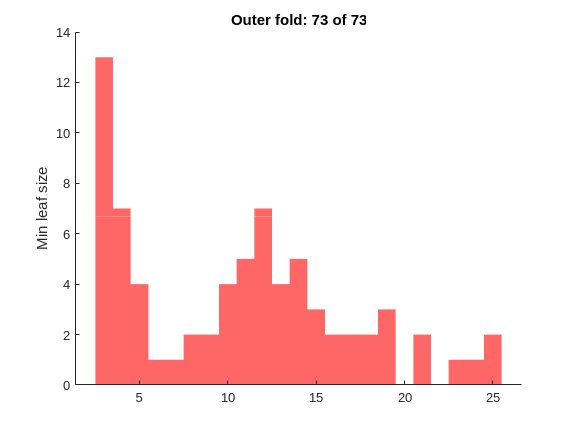

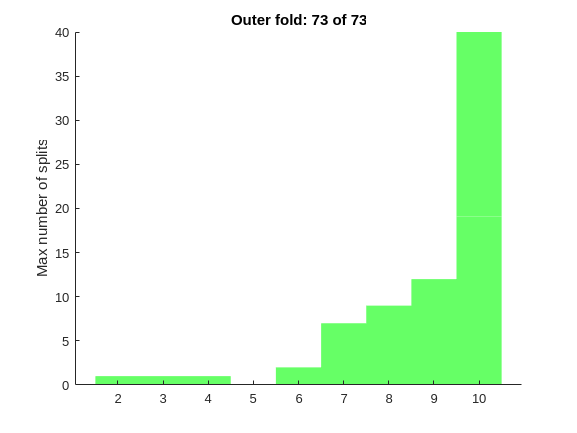

dispSwitch = false; % if true, will display text otherwise results are output in figures
for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    mdl = fitctree(trX,trY,'OptimizeHyperparameters',hype,'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false),'PredictorSelection','interaction-curvature','Surrogate','on');    
    
    % use this code to pass in the inner folds we previously generated
    % instead. Note, we cannot repartition them so we turn that off...
      %mdl = fitctree(trX,trY,'OptimizeHyperparameters',hype,'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
      %'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'CVPartition',c2{i},'Verbose',0,'MaxObjectiveEvaluations',300,'Repartition',false,'ShowPlots',false),'PredictorSelection','interaction-curvature','Surrogate','on');

    yh(test(c,i)) = predict(mdl,teX);
    ms(i) = mdl.ModelParameters.MaxSplits;
    ml(i) = mdl.ModelParameters.MinLeaf;

    if dispSwitch
        disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        disp(['     -Leaf: ' num2str(mdl.ModelParameters.MinLeaf)])
        disp(['     -MaxSplit: ' num2str(mdl.ModelParameters.MaxSplits)])
    else
        if i == 1
            f = figure;
            h = figure;
        end
        figure(f)
        histogram(ms,'DisplayName','Classes','FaceColor',[1 0 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Min leaf size')
        figure(h)
        histogram(ml,'DisplayName','Classes','FaceColor',[0 1 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Max number of splits')
    end
end

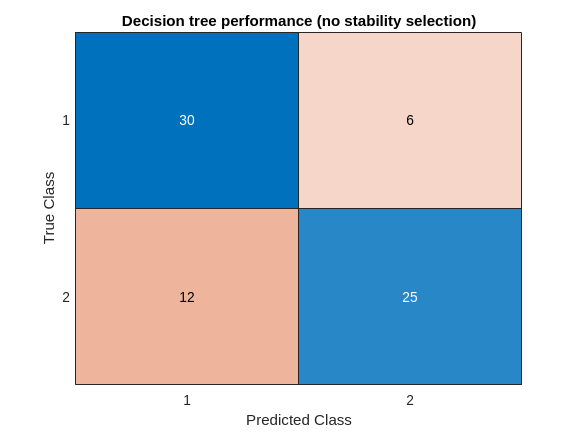

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('Decision tree performance (no stability selection)')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.75342


I got 75% when I ran this. Your number might vary slightly due to the stochasticity of the algorithms and partition assignments. You should see something in the range of ~74%-77%, which is what I've tended to see on my end. Note, precision differs between OS's and your results may still vary slightly.

Now let's repeat the model building procedure but add stabSel into the pipeline. We'll use stabSel on our training datasets, then tune models in the inner folds using the dataset restricted to stabSel-selected features. Remember, we are subsampling the training datasets during feature selection, which should help with overfitting. In any case, our test data is completely independent.

This was an early project, before stabSel was as comprehensive. As such we'll run stabSel in the most basic way. We'll just retain any feature with > 45% empirical probability of selection across subsamples. In each subsample, we'll use Kullback-Leibler divergence to select the top 5 features. Each subsample will include just north of half the dataset (60%). 

Outer fold: 1 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 2 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 3 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 4 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 5 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 6 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 7 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 8 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 9 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 10 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 11 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 12 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 13 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 14 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 15 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 16 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 17 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 18 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 19 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 20 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 21 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 22 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 23 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 24 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 25 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 26 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 27 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 28 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 29 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 30 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 31 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 32 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 33 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 34 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 35 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 36 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 37 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 38 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 39 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 40 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 41 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 42 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 43 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 44 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 45 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 46 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 47 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 48 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 49 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 50 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 51 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 52 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 53 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 54 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 55 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 56 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 57 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 58 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 59 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 60 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 61 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 62 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 63 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 64 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 65 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 66 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 67 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 68 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 69 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 70 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 71 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 72 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


Outer fold: 73 of 73


Probability threshold for features to enter stable set was calculated to be: 1.125
Effective FDR-like p-value is: 0.2. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison error rate p-value is: 0.05
Effective per-family error rate p-value is: 1


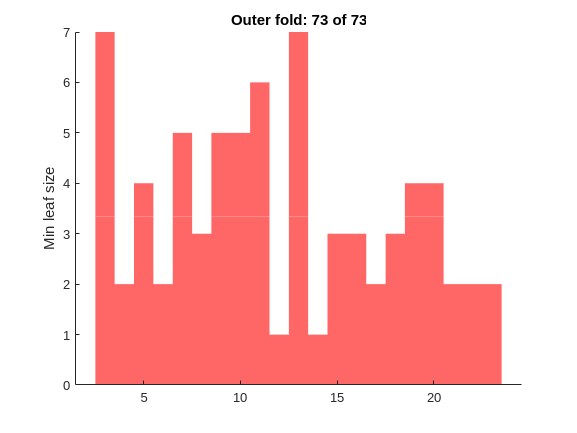

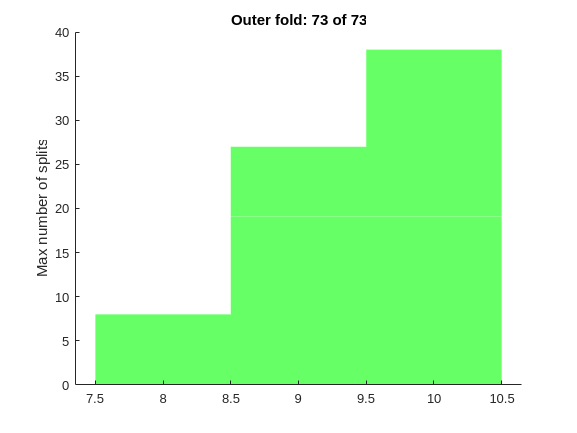

clear nl ms ml
for i = 1:c.NumTestSets
    disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = preds(training(c,i),:); 
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    [~,~,klSel{i},~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY',...
                'selAlgo','entropy','fixMax',false,'stnd',false,'compPars',false,'samType','subsample','filter',true,...
                'maxVars',5,'thresh',[],'numFalsePos',1,'rep',250,'prop',0.6,'parallel',true,'verbose',false);
                        
    id = find(klSel{i} > 0.4); % find features with empirical probability of selection of at least 40%
    mdl = fitctree(trX(:,id),trY,'OptimizeHyperparameters',hype,'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false),'PredictorSelection','interaction-curvature','Surrogate','on');    
    

    yhDKL(test(c,i)) = predict(mdl,teX(:,id));
    msF(i) = mdl.ModelParameters.MaxSplits;
    mlF(i) = mdl.ModelParameters.MinLeaf;

    if dispSwitch
        disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        disp(['     -Leaf: ' num2str(mdl.ModelParameters.MinLeaf)])
        disp(['     -MaxSplit: ' num2str(mdl.ModelParameters.MaxSplits)])
    else
        if i == 1
            f = figure;
            h = figure;
        end
        figure(f)
        histogram(msF,'DisplayName','Classes','FaceColor',[1 0 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Min leaf size')
        figure(h)
        histogram(mlF,'DisplayName','Classes','FaceColor',[0 1 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Max number of splits')
    end
end

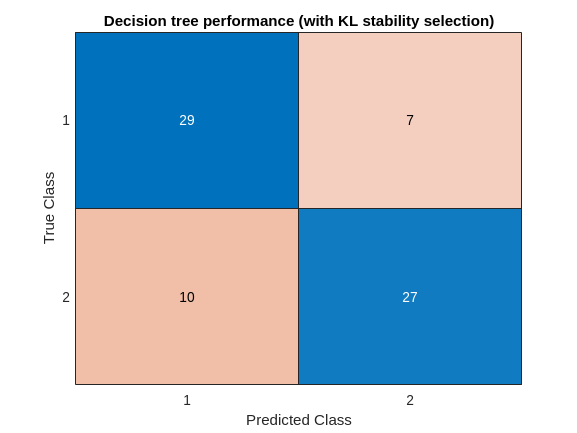

[conDKL] = confusionmat(y,yhDKL);
figure; confusionchart(conDKL); title('Decision tree performance (with KL stability selection)')

disp(['Accuracy of model is: ' num2str(sum(y==yhDKL)./length(y))])

Accuracy of model is: 0.76712


As you can see, stability selection apparently makes no substantial difference on model performance here. Again, your results might vay, but if you do see a difference, it should be very minor. In the two times I ran this code, I saw no difference and as you see from the inline results here, a difference of just ~0.01 in accuracy. Note also that if you rerun this code and change the criterion for retaining features from 40%-50% empirical probability of selection, you will get the same results.

## Investigating consistency of stability selection

Since we have saved out our selected features, let's take a look at the most consistent ones.

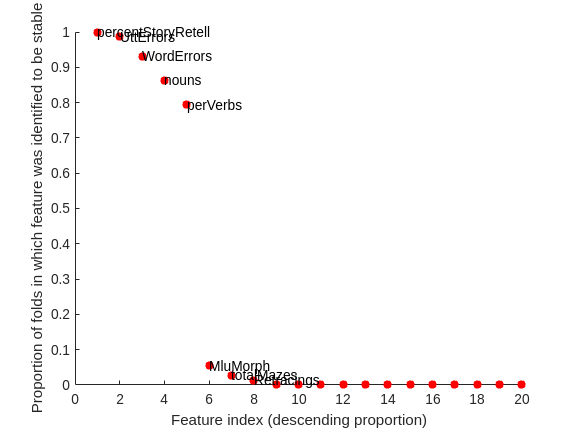

vars = extractBefore(extractAfter(inData.Properties.VariableNames([1:19 21]),'x_'),'_'); % get variable names
klSelFq = zeros(1,size(preds,2)); % preallocate matrix showing number of times feature was stable across folds
for i = 1:length(klSel) % loop over each instance of stability selection (i.e., each outer fold)
    id = find(klSel{i} > 0.4); % retain our "stable" features
    klSelFq(id) = klSelFq(id)+1; % count features
end
klSelFq=klSelFq./length(klSel); % change counts to proportion of times feature is stable
[sv,si] = sort(klSelFq,'descend'); % sort features by descending proportions
figure; scatter([1:length(klSelFq)],sv,'filled','MarkerFaceColor',[1 0 0]) % plot
ylabel('Proportion of folds in which feature was identified to be stable')
xlabel('Feature index (descending proportion)')
hold on % add text to top features
for i = 1:8
    text(i,sv(i),vars(si(i)))
end

Note, we used more subsamples in our ms so your results here may vary slightly. However, you should see % story being the only feature identified as stable in every fold. You should also see % verbs, utterance errors, word errors and nouns as the most stable features. Further, MLU morphs, retracings and total mazes should be the only features you see that are selected very rarely.

You can see the decision tree run on all of the data is capitalizing on the feature that was deemed most stable by stability selection when we collapse across all outer folds. 

## Comparing decision trees to random forests

Let's see if we can get even better performance if we increase the complexity of our decision tree using a random forest. As before, we will use fewer evaluations for tuning just to speed this up (this can take quite some time to run).

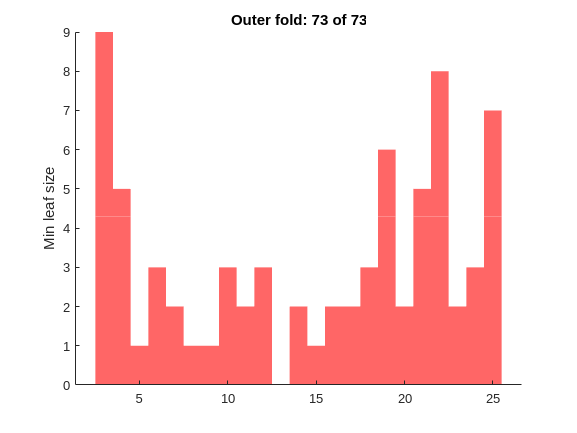

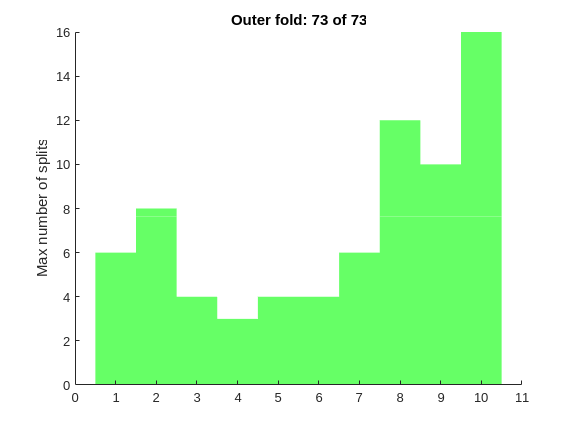

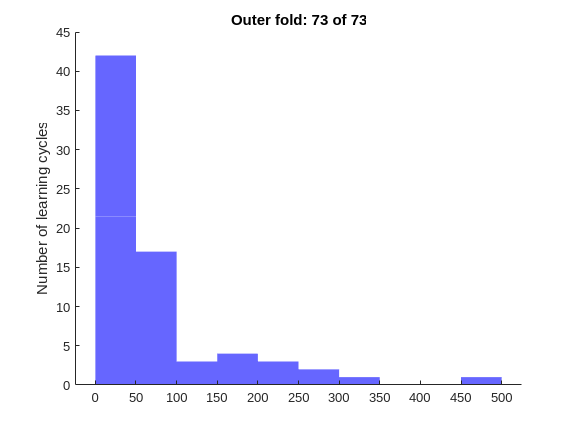

clear nl ms ml
hype = hyperparameters('fitcensemble',preds,y,'Tree');
hype(1).Optimize = false; % we want to use bagging so that we achieve a random forest so set this to false
hype(3).Optimize = false; % learning rate does not apply to bagging so false here as well

% the settings below are taken from our decision tree model but indices
% inside hype differ
hype(4).Range = [1 10]; % a tree with more leaves is more complex. Let's prune it to a reasonable 10 leaves.
hype(5).Range = [3 25]; % a tree with more splits is also more complex. Here, we'll roughly halve the number of splits set by default. Since we are discouraging complexity we'll increase the smallest number of maximum splits from 1 to 3, encouraging some model complexity but "within reason".
hype(4).Transform = 'none'; % since we have drastically constrained our parameter search space, log is not necessary and may undersample appropriate hyperparameters
hype(5).Transform = 'none';
hype(2).Optimize = true; % make sure we optimize for max number of splits, which does not occur by default
hype(5).Optimize = true; % optimize split criterion. We did this in the final ms but you will have to increase the number of evaluations to properly tune this, which will take longer to run 
hype(4).Optimize = true; % double check no tuning of number of variables to sample. This is because we don't have that many variables in the first place

dispSwitch = false; % if true, will display text otherwise results are output in figures
for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    t = templateTree('PredictorSelection','interaction-curvature','Surrogate','on');
    mdl = fitcensemble(trX,trY,'Learners',t,'Method','bag','OptimizeHyperparameters',hype,'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',25,'Repartition',true,'ShowPlots',false));    
    
    yh(test(c,i)) = predict(mdl,teX);
    nl(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.NumLearningCycles;
    ms(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.MaxNumSplits;
    ml(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.MinLeafSize;

    if dispSwitch
        disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        disp(['     -Leaf: ' num2str(ml(i))])
        disp(['     -MaxSplit: ' num2str(ms(i))])
        disp(['     -NumLearningCycles: ' num2str(nl(i))])
    else
        if i == 1
            f = figure;
            h = figure;
            j = figure;
        end
        figure(f)
        histogram(ms,'DisplayName','Classes','FaceColor',[1 0 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Min leaf size')
        figure(h)
        histogram(ml,'DisplayName','Classes','FaceColor',[0 1 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Max number of splits')
        figure(j)
        histogram(nl,'DisplayName','Classes','FaceColor',[0 0 1],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Number of learning cycles')
    end
end

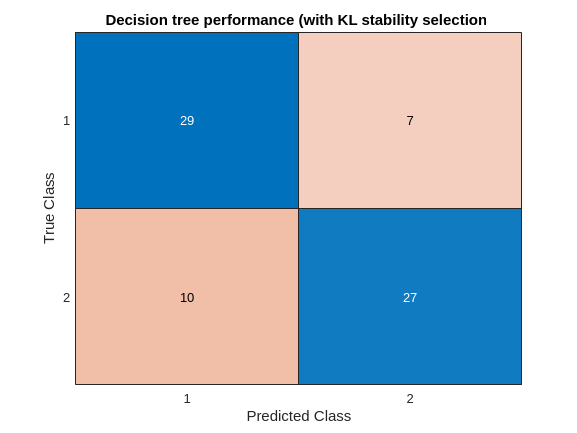

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('Random forest performance')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.76712


As you can see, even though it took SO MUCH LONGER to run the random forest models, they don't do much better than a decision tree. This is a good indicator that model complexity does not matter too much for our task. Note, if you remove our hyperparameter restrictions here, you will still get a random forest that performs as well (for example, if you think bagging will sufficiently prevent overfitting).

Now let's run the same exact random forest models but use the stability selection features. Will this improve performance?

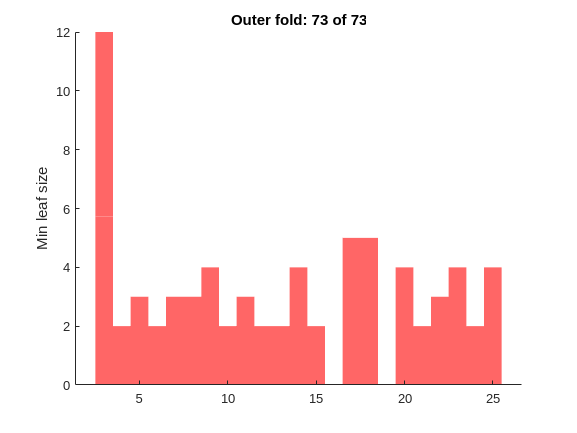

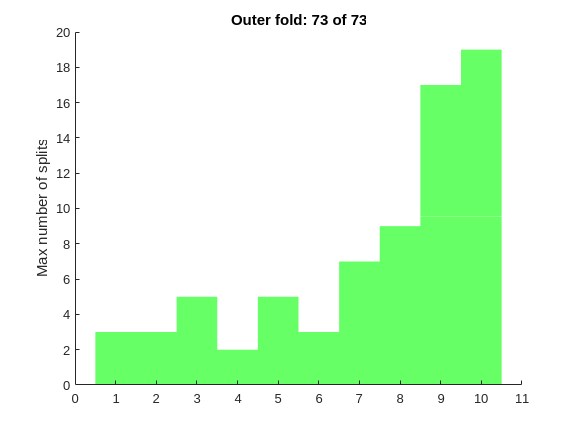

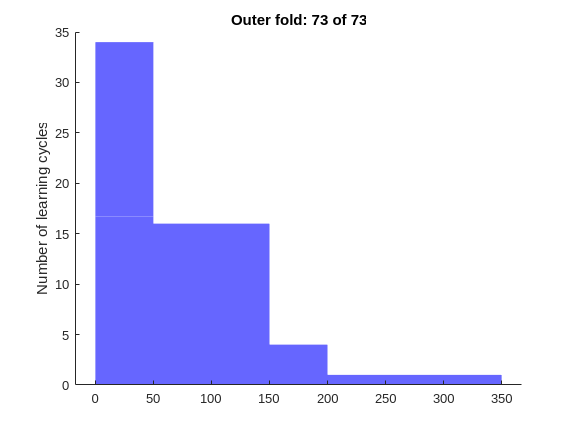

clear nl ms ml
hype = hyperparameters('fitcensemble',preds,y,'Tree');
hype(1).Optimize = false; % we want to use bagging so that we achieve a random forest so set this to false
hype(3).Optimize = false; % learning rate does not apply to bagging so false here as well

% the settings below are taken from our decision tree model but indices
% inside hype differ
hype(4).Range = [1 10]; % a tree with more leaves is more complex. Let's prune it to a reasonable 10 leaves.
hype(5).Range = [3 25]; % a tree with more splits is also more complex. Here, we'll roughly halve the number of splits set by default. Since we are discouraging complexity we'll increase the smallest number of maximum splits from 1 to 3, encouraging some model complexity but "within reason".
hype(4).Transform = 'none'; % since we have drastically constrained our parameter search space, log is not necessary and may undersample appropriate hyperparameters
hype(5).Transform = 'none';
hype(2).Optimize = true; % make sure we optimize for max number of splits, which does not occur by default
hype(5).Optimize = true; % optimize split criterion. We did this in the final ms but you will have to increase the number of evaluations to properly tune this, which will take longer to run 
hype(4).Optimize = true; % double check no tuning of number of variables to sample. This is because we don't have that many variables in the first place

dispSwitch = false; % if true, will display text otherwise results are output in figures
for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    id = find(klSel{i} > 0.4);

    t = templateTree('PredictorSelection','interaction-curvature','Surrogate','on');
    mdl = fitcensemble(trX(:,id),trY,'Learners',t,'Method','bag','OptimizeHyperparameters',hype,'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',25,'Repartition',true,'ShowPlots',false));    
    
    yh(test(c,i)) = predict(mdl,teX(:,id));
    nl(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.NumLearningCycles;
    ms(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.MaxNumSplits;
    ml(i) = mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective.MinLeafSize;

    if dispSwitch
        disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        disp(['     -Leaf: ' num2str(ml(i))])
        disp(['     -MaxSplit: ' num2str(ms(i))])
        disp(['     -NumLearningCycles: ' num2str(nl(i))])
    else
        if i == 1
            f = figure;
            h = figure;
            j = figure;
        end
        figure(f)
        histogram(ms,'DisplayName','Classes','FaceColor',[1 0 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Min leaf size')
        figure(h)
        histogram(ml,'DisplayName','Classes','FaceColor',[0 1 0],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Max number of splits')
        figure(j)
        histogram(nl,'DisplayName','Classes','FaceColor',[0 0 1],'EdgeAlpha',0); box off
        title(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
        ylabel('Number of learning cycles')
    end
end

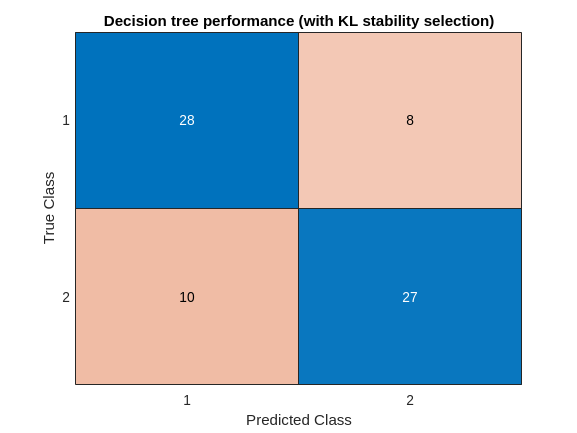

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('Random forest performance (with KL stability selection)')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.75342


I got *identical* results when using stability selection here. Let's move on to some other algorithms that will benefit from stability selection.

## Building a kNN model

We'll use default hyperparameter settings for kNN since they're pretty reasonable. This will use all the data (no feature selection). Since we have some categorical variables, we'll print to display instead of updating a histogram of the selected hyperparameters on each fold. 

for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    mdl = fitcknn(trX,trY,'Standardize',true,'OptimizeHyperparameters',{'Distance','NumNeighbors','DistanceWeight'},'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
        'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false));

    yh(test(c,i)) = predict(mdl,teX);
    disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
    disp(mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective)
end

Outer fold: 1 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         2          seuclidean        equal     


Outer fold: 2 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         minkowski       inverse    


Outer fold: 3 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         25         minkowski    squaredinverse


Outer fold: 4 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         29         euclidean        equal     


Outer fold: 5 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         10         minkowski    squaredinverse


Outer fold: 6 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         4          correlation       inverse    


Outer fold: 7 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         14         correlation        equal     


Outer fold: 8 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         3          mahalanobis       inverse    


Outer fold: 9 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         6          minkowski    squaredinverse


Outer fold: 10 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         9          seuclidean        equal     


Outer fold: 11 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         minkowski        equal     


Outer fold: 12 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         15         chebychev       inverse    


Outer fold: 13 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         minkowski        equal     


Outer fold: 14 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         2           cosine        inverse    


Outer fold: 15 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         3          mahalanobis    squaredinverse


Outer fold: 16 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         36         chebychev       inverse    


Outer fold: 17 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         3          mahalanobis       inverse    


Outer fold: 18 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         25         chebychev       inverse    


Outer fold: 19 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         16         euclidean    squaredinverse


Outer fold: 20 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         3           cosine        inverse    


Outer fold: 21 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         3          correlation       inverse    


Outer fold: 22 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         minkowski       inverse    


Outer fold: 23 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         9          seuclidean        equal     


Outer fold: 24 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         14         minkowski    squaredinverse


Outer fold: 25 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         16         euclidean       inverse    


Outer fold: 26 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         5          chebychev       inverse    


Outer fold: 27 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         36         correlation    squaredinverse


Outer fold: 28 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         9          seuclidean    squaredinverse


Outer fold: 29 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         8          euclidean        equal     


Outer fold: 30 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         11         minkowski    squaredinverse


Outer fold: 31 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         36         correlation    squaredinverse


Outer fold: 32 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         25         chebychev       inverse    


Outer fold: 33 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         9          minkowski       inverse    


Outer fold: 34 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         minkowski       inverse    


Outer fold: 35 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         31         seuclidean    squaredinverse


Outer fold: 36 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         16          cosine         equal     


Outer fold: 37 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         minkowski       inverse    


Outer fold: 38 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         14         euclidean       inverse    


Outer fold: 39 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         8          euclidean        equal     


Outer fold: 40 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         2          correlation        equal     


Outer fold: 41 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         12         correlation    squaredinverse


Outer fold: 42 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         16         minkowski       inverse    


Outer fold: 43 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         6          euclidean        equal     


Outer fold: 44 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         14         minkowski       inverse    


Outer fold: 45 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         11         seuclidean       inverse    


Outer fold: 46 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         20         chebychev       inverse    


Outer fold: 47 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         1          spearman    squaredinverse


Outer fold: 48 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         5          chebychev       inverse    


Outer fold: 49 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         4          mahalanobis       inverse    


Outer fold: 50 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         4          seuclidean       inverse    


Outer fold: 51 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         3          euclidean       inverse    


Outer fold: 52 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         7          euclidean       inverse    


Outer fold: 53 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         minkowski       inverse    


Outer fold: 54 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         12         correlation    squaredinverse


Outer fold: 55 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         27         minkowski        equal     


Outer fold: 56 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         11         minkowski        equal     


Outer fold: 57 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         13         seuclidean        equal     


Outer fold: 58 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         10         euclidean        equal     


Outer fold: 59 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         7          seuclidean       inverse    


Outer fold: 60 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         15         minkowski        equal     


Outer fold: 61 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         5          seuclidean       inverse    


Outer fold: 62 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         9           cosine        inverse    


Outer fold: 63 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         7          minkowski    squaredinverse


Outer fold: 64 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         15         seuclidean    squaredinverse


Outer fold: 65 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         2          correlation        equal     


Outer fold: 66 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         8          euclidean       inverse    


Outer fold: 67 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         12         seuclidean       inverse    


Outer fold: 68 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         27         chebychev    squaredinverse


Outer fold: 69 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         3           cosine        inverse    


Outer fold: 70 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         36         spearman       inverse    


Outer fold: 71 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         2          correlation        equal     


Outer fold: 72 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         4          correlation       inverse    


Outer fold: 73 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         14         seuclidean        equal     


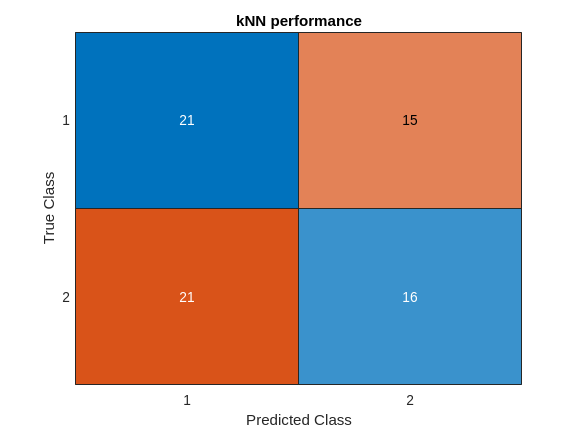

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('kNN performance')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.50685


Wow, that was `bad`! Let's see if we can get any better through stabSel...

for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));
    id = find(klSel{i} > 0.4); % find features with empirical probability of selection of at least 40%

    mdl = fitcknn(trX(:,id),trY,'Standardize',true,'OptimizeHyperparameters',{'Distance','NumNeighbors','DistanceWeight'},'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
        'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false));

    yh(test(c,i)) = predict(mdl,teX(:,id));
    disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
    disp(mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective)
end

Outer fold: 1 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         8          mahalanobis       inverse    


Outer fold: 2 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         21         minkowski       inverse    


Outer fold: 3 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         16          cosine        inverse    


Outer fold: 4 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         36         seuclidean    squaredinverse


Outer fold: 5 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         15         euclidean    squaredinverse


Outer fold: 6 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         33         chebychev    squaredinverse


Outer fold: 7 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         34         seuclidean       inverse    


Outer fold: 8 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         34         minkowski    squaredinverse


Outer fold: 9 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         14         seuclidean       inverse    


Outer fold: 10 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         15         euclidean    squaredinverse


Outer fold: 11 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         22         minkowski       inverse    


Outer fold: 12 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         35         minkowski    squaredinverse


Outer fold: 13 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         20          cosine        inverse    


Outer fold: 14 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         12          cosine        inverse    


Outer fold: 15 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         20         seuclidean    squaredinverse


Outer fold: 16 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         12          cosine        inverse    


Outer fold: 17 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         14         spearman       inverse    


Outer fold: 18 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         12         mahalanobis        equal     


Outer fold: 19 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         16          cosine        inverse    


Outer fold: 20 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         27         correlation       inverse    


Outer fold: 21 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         cityblock       inverse    


Outer fold: 22 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         36         chebychev    squaredinverse


Outer fold: 23 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         10         correlation       inverse    


Outer fold: 24 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         12         seuclidean       inverse    


Outer fold: 25 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         20          cosine        inverse    


Outer fold: 26 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         36          cosine        inverse    


Outer fold: 27 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         31         spearman    squaredinverse


Outer fold: 28 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         36         minkowski    squaredinverse


Outer fold: 29 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         22         correlation       inverse    


Outer fold: 30 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         36         chebychev    squaredinverse


Outer fold: 31 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         18          cosine        inverse    


Outer fold: 32 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         8          chebychev    squaredinverse


Outer fold: 33 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         17          cosine        inverse    


Outer fold: 34 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         36         cityblock    squaredinverse


Outer fold: 35 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         8          seuclidean       inverse    


Outer fold: 36 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         15         euclidean    squaredinverse


Outer fold: 37 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         25         chebychev    squaredinverse


Outer fold: 38 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         10         seuclidean        equal     


Outer fold: 39 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         14         minkowski       inverse    


Outer fold: 40 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         36          cosine        inverse    


Outer fold: 41 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         chebychev       inverse    


Outer fold: 42 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         27         euclidean       inverse    


Outer fold: 43 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         31          cosine        inverse    


Outer fold: 44 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         17          cosine        inverse    


Outer fold: 45 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         36          cosine        inverse    


Outer fold: 46 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         21          cosine        inverse    


Outer fold: 47 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         10         euclidean       inverse    


Outer fold: 48 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         13         seuclidean       inverse    


Outer fold: 49 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         25         seuclidean    squaredinverse


Outer fold: 50 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         12         minkowski       inverse    


Outer fold: 51 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         21         seuclidean    squaredinverse


Outer fold: 52 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         23          cosine        inverse    


Outer fold: 53 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         22         seuclidean    squaredinverse


Outer fold: 54 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         36         seuclidean    squaredinverse


Outer fold: 55 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         36         mahalanobis    squaredinverse


Outer fold: 56 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         20         minkowski    squaredinverse


Outer fold: 57 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         cityblock    squaredinverse


Outer fold: 58 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         32         chebychev    squaredinverse


Outer fold: 59 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         8          euclidean        equal     


Outer fold: 60 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         9          correlation        equal     


Outer fold: 61 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         22         seuclidean    squaredinverse


Outer fold: 62 of 73


    NumNeighbors    Distance    DistanceWeight
    ____________    ________    ______________
         32          cosine        inverse    


Outer fold: 63 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         5          mahalanobis       inverse    


Outer fold: 64 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         31         euclidean    squaredinverse


Outer fold: 65 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         18         correlation       inverse    


Outer fold: 66 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         27         correlation        equal     


Outer fold: 67 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         31         seuclidean       inverse    


Outer fold: 68 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         13         chebychev    squaredinverse


Outer fold: 69 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         17         seuclidean    squaredinverse


Outer fold: 70 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         33         minkowski    squaredinverse


Outer fold: 71 of 73


    NumNeighbors     Distance     DistanceWeight
    ____________    __________    ______________
         14         seuclidean       inverse    


Outer fold: 72 of 73


    NumNeighbors     Distance      DistanceWeight
    ____________    ___________    ______________
         21         correlation       inverse    


Outer fold: 73 of 73


    NumNeighbors    Distance     DistanceWeight
    ____________    _________    ______________
         31         chebychev    squaredinverse


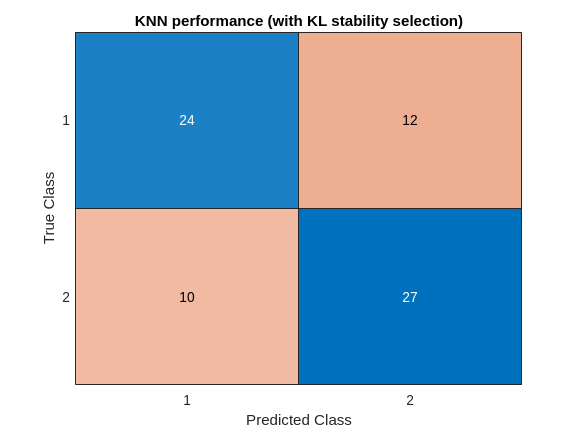

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('KNN performance (with KL stability selection)')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.69863


You can see stability selection made a HUGE difference. Claerly having fewer noisy or redundant features permits better model tuning. Indeed, here we see performance slightly better than what we reported in the ms (not by much, one additional patient classified correctly which may reflect partitioning noise). 

Let's try one last algorithm--svm. Here too we will use auto selected hyperparameters by matlab since the value of the hyperamaters in a SVM are less clearly related to model complexity compared to something like a decision tree (e.g., higher box constraint may mean greater likelihood of overfitting but it's not clear what a reasonable range is a priori in the same way as say a maximum of 25 splits in our decision tree, which will have access to ~20 variables). 

for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    mdl = fitcsvm(trX,trY,'Standardize',true,'KernelScale','auto','OptimizeHyperparameters',{'BoxConstraint','KernelFunction','PolynomialOrder'},'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
        'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false));

    yh(test(c,i)) = predict(mdl,teX);
    disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
    disp(mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective)
end

Outer fold: 1 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.44267           linear              NaN      


Outer fold: 2 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.1528            linear              NaN      


Outer fold: 3 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       150.03           gaussian             NaN      


Outer fold: 4 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.96203           linear              NaN      


Outer fold: 5 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.39222           linear              NaN      


Outer fold: 6 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.60963           linear              NaN      


Outer fold: 7 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.0702            linear              NaN      


Outer fold: 8 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.82816           linear              NaN      


Outer fold: 9 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.34621           linear              NaN      


Outer fold: 10 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.39325           linear              NaN      


Outer fold: 11 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.48708           linear              NaN      


Outer fold: 12 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.3534            linear              NaN      


Outer fold: 13 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.31728           linear              NaN      


Outer fold: 14 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.35463           linear              NaN      


Outer fold: 15 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.64449           linear              NaN      


Outer fold: 16 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.76458           linear              NaN      


Outer fold: 17 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.41728           linear              NaN      


Outer fold: 18 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.53585           linear              NaN      


Outer fold: 19 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.28834           linear              NaN      


Outer fold: 20 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.17346           linear              NaN      


Outer fold: 21 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.1583            linear              NaN      


Outer fold: 22 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.0247            linear              NaN      


Outer fold: 23 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
        1.04           polynomial             2       


Outer fold: 24 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.010033           linear              NaN      


Outer fold: 25 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.1573            linear              NaN      


Outer fold: 26 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.8796            linear              NaN      


Outer fold: 27 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.91798           linear              NaN      


Outer fold: 28 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       3.5879            linear              NaN      


Outer fold: 29 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.41562         polynomial             2       


Outer fold: 30 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       226.63           gaussian             NaN      


Outer fold: 31 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       2.4589            linear              NaN      


Outer fold: 32 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.67528           linear              NaN      


Outer fold: 33 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.98465           linear              NaN      


Outer fold: 34 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.88329           linear              NaN      


Outer fold: 35 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.32243           linear              NaN      


Outer fold: 36 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.71057           linear              NaN      


Outer fold: 37 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.31302           linear              NaN      


Outer fold: 38 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       27.827           gaussian             NaN      


Outer fold: 39 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.73856           linear              NaN      


Outer fold: 40 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.29038           linear              NaN      


Outer fold: 41 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
        1.561            linear              NaN      


Outer fold: 42 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.31719           linear              NaN      


Outer fold: 43 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.39164           linear              NaN      


Outer fold: 44 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.1304            linear              NaN      


Outer fold: 45 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.40626           linear              NaN      


Outer fold: 46 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       4.0585           gaussian             NaN      


Outer fold: 47 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.88145         polynomial             3       


Outer fold: 48 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.94381           linear              NaN      


Outer fold: 49 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.78027           linear              NaN      


Outer fold: 50 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.41591           linear              NaN      


Outer fold: 51 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.22889           linear              NaN      


Outer fold: 52 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.42137           linear              NaN      


Outer fold: 53 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.65958           linear              NaN      


Outer fold: 54 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.5289            linear              NaN      


Outer fold: 55 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.45916           linear              NaN      


Outer fold: 56 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       4.6715            linear              NaN      


Outer fold: 57 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.2402            linear              NaN      


Outer fold: 58 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.049191           linear              NaN      


Outer fold: 59 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.15472           linear              NaN      


Outer fold: 60 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.4668            linear              NaN      


Outer fold: 61 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.45955           linear              NaN      


Outer fold: 62 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.04683           linear              NaN      


Outer fold: 63 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.49485           linear              NaN      


Outer fold: 64 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.46546           linear              NaN      


Outer fold: 65 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.0437            linear              NaN      


Outer fold: 66 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.46859           linear              NaN      


Outer fold: 67 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.61681           linear              NaN      


Outer fold: 68 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.33439           linear              NaN      


Outer fold: 69 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.30477           linear              NaN      


Outer fold: 70 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       2.1116            linear              NaN      


Outer fold: 71 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       40.113          polynomial             4       


Outer fold: 72 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.67114           linear              NaN      


Outer fold: 73 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       3.7889           gaussian             NaN      


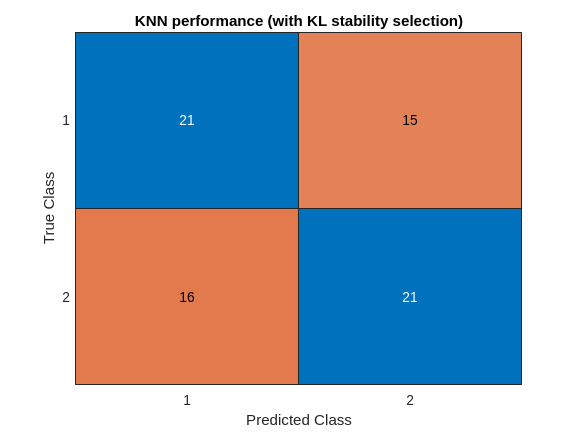

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('SVM performance')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.57534


This is particuarly bad! Let's try stability selection...

for i = 1:c.NumTestSets
    trX = preds(training(c,i),:);
    trY = y(training(c,i));
    teX = preds(test(c,i),:);
    teY = y(test(c,i));

    id = find(klSel{i} > 0.4); % find features with empirical probability of selection of at least 40%

    mdl = fitcsvm(trX(:,id),trY,'Standardize',true,'KernelScale','auto','OptimizeHyperparameters',{'BoxConstraint','KernelFunction','PolynomialOrder'},'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
        'expected-improvement-plus','Optimizer','bayesopt','UseParallel',true,'KFold',8,'Verbose',0,'MaxObjectiveEvaluations',50,'Repartition',true,'ShowPlots',false));

    yh(test(c,i)) = predict(mdl,teX(:,id));
    disp(['Outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets)])
    disp(mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective)
end

Outer fold: 1 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.27829         polynomial             2       


Outer fold: 2 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       2.2428           gaussian             NaN      


Outer fold: 3 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.023943           linear              NaN      


Outer fold: 4 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.07348         polynomial             2       


Outer fold: 5 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.097608         polynomial             2       


Outer fold: 6 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.036282         polynomial             2       


Outer fold: 7 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.021557         polynomial             2       


Outer fold: 8 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       5.4118           gaussian             NaN      


Outer fold: 9 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.061074         polynomial             3       


Outer fold: 10 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.015148         polynomial             3       


Outer fold: 11 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.014305         polynomial             3       


Outer fold: 12 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.050744         polynomial             3       


Outer fold: 13 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.8418           gaussian             NaN      


Outer fold: 14 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.029843         polynomial             3       


Outer fold: 15 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.6232           gaussian             NaN      


Outer fold: 16 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.029304         polynomial             3       


Outer fold: 17 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.019746          gaussian             NaN      


Outer fold: 18 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       5.4908            linear              NaN      


Outer fold: 19 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.68959         polynomial             2       


Outer fold: 20 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       102.15          polynomial             2       


Outer fold: 21 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.020886         polynomial             3       


Outer fold: 22 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.24465         polynomial             2       


Outer fold: 23 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.097999         polynomial             3       


Outer fold: 24 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.083892         polynomial             2       


Outer fold: 25 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       200.39            linear              NaN      


Outer fold: 26 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       4.6249           gaussian             NaN      


Outer fold: 27 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.061865           linear              NaN      


Outer fold: 28 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.22609         polynomial             2       


Outer fold: 29 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.18666         polynomial             2       


Outer fold: 30 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.018579         polynomial             3       


Outer fold: 31 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.025571         polynomial             3       


Outer fold: 32 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.025923         polynomial             3       


Outer fold: 33 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       2.9561           gaussian             NaN      


Outer fold: 34 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.064472         polynomial             2       


Outer fold: 35 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.11177         polynomial             2       


Outer fold: 36 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.065449          gaussian             NaN      


Outer fold: 37 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.35282         polynomial             2       


Outer fold: 38 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.092803           linear              NaN      


Outer fold: 39 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.07451           linear              NaN      


Outer fold: 40 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.37751          gaussian             NaN      


Outer fold: 41 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.042594         polynomial             3       


Outer fold: 42 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.4284           gaussian             NaN      


Outer fold: 43 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       1.6208           gaussian             NaN      


Outer fold: 44 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.04873         polynomial             3       


Outer fold: 45 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.0098624        polynomial             4       


Outer fold: 46 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.41063          gaussian             NaN      


Outer fold: 47 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.10221         polynomial             2       


Outer fold: 48 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.02806         polynomial             2       


Outer fold: 49 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.09624         polynomial             2       


Outer fold: 50 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.020732         polynomial             3       


Outer fold: 51 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       156.08            linear              NaN      


Outer fold: 52 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.45119          gaussian             NaN      


Outer fold: 53 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.016512          gaussian             NaN      


Outer fold: 54 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.064936           linear              NaN      


Outer fold: 55 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.15063         polynomial             2       


Outer fold: 56 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.033941         polynomial             3       


Outer fold: 57 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.06787         polynomial             2       


Outer fold: 58 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.1529            linear              NaN      


Outer fold: 59 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.072095           linear              NaN      


Outer fold: 60 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.0738          polynomial             2       


Outer fold: 61 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.012459         polynomial             4       


Outer fold: 62 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.4689           gaussian             NaN      


Outer fold: 63 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.056362         polynomial             2       


Outer fold: 64 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.1082          polynomial             2       


Outer fold: 65 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
        2.819           gaussian             NaN      


Outer fold: 66 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.023048           linear              NaN      


Outer fold: 67 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.024408          gaussian             NaN      


Outer fold: 68 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.038754         polynomial             3       


Outer fold: 69 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
        4.837           gaussian             NaN      


Outer fold: 70 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
       0.46686          gaussian             NaN      


Outer fold: 71 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.086928           linear              NaN      


Outer fold: 72 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.025969         polynomial             3       


Outer fold: 73 of 73


    BoxConstraint    KernelFunction    PolynomialOrder
    _____________    ______________    _______________
      0.045478         polynomial             3       


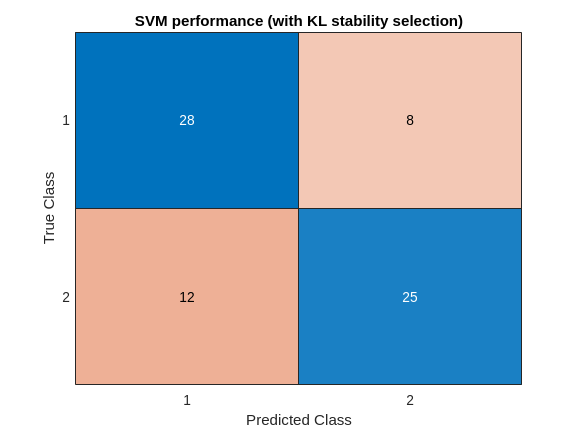

[con] = confusionmat(y,yh);
figure; confusionchart(con); title('SVM performance (with KL stability selection)')

disp(['Accuracy of model is: ' num2str(sum(y==yh)./length(y))])

Accuracy of model is: 0.72603


You can see the improvement is quite dramatic for SVMs. Here again, if you tune for longer you would probably find better performance just as we did the first time that we ran this. 